# Lecture: Solving Transient Heat Equation

**Video description of the live script is available **[**here**](https://www.youtube.com/watch?v=mICYVEwe6Jg&list=PLn8PRpmsu08oV_uJZBB7jIemn4-lxN7yL&index=4)**.**

Switch working directory to folder containing this file.

editor = matlab.desktop.editor.getActive;
% Check if there is an open file
if ~isempty(editor)
    % Get the full path of the current open file
    currentFilePath = editor.Filename;
    
    % Extract the folder path from the full file path
    [currentFileFolder, ~, ~] = fileparts(currentFilePath);
    
    % Get the current working directory
    currentDir = pwd;
    
    % Check if the working directory is different from the file's folder
    if ~strcmp(currentDir, currentFileFolder)
        % Change the working directory to the file's folder
        cd(currentFileFolder);
        fprintf('Changed working directory to: %s\n', currentFileFolder);
    else
        fprintf('Already in the correct directory: %s\n', currentDir);
    end
else
    fprintf('No file is currently open in the MATLAB Editor.\n');
end

## ************* PART I : PROBLEM  ********** ***

## *Story*

### *Problem*

- Analyze **heat diffusion along an thin rod **and compute **absolute temperature **$u\left(x,t\right)\;\ldotp$ 

- **"Transient" **problem**: **we are given **initial temperature **and **hold boundaries at fixed 0°K.**

- Input data: **material, length **$L>0$**,  initial temperature **$u\left(x,0\right)=\phi \left(x\right)$at time $t=0$

- Assumptions: 1-dim, finite positive length, isotropic material, no heat exchange with external environment

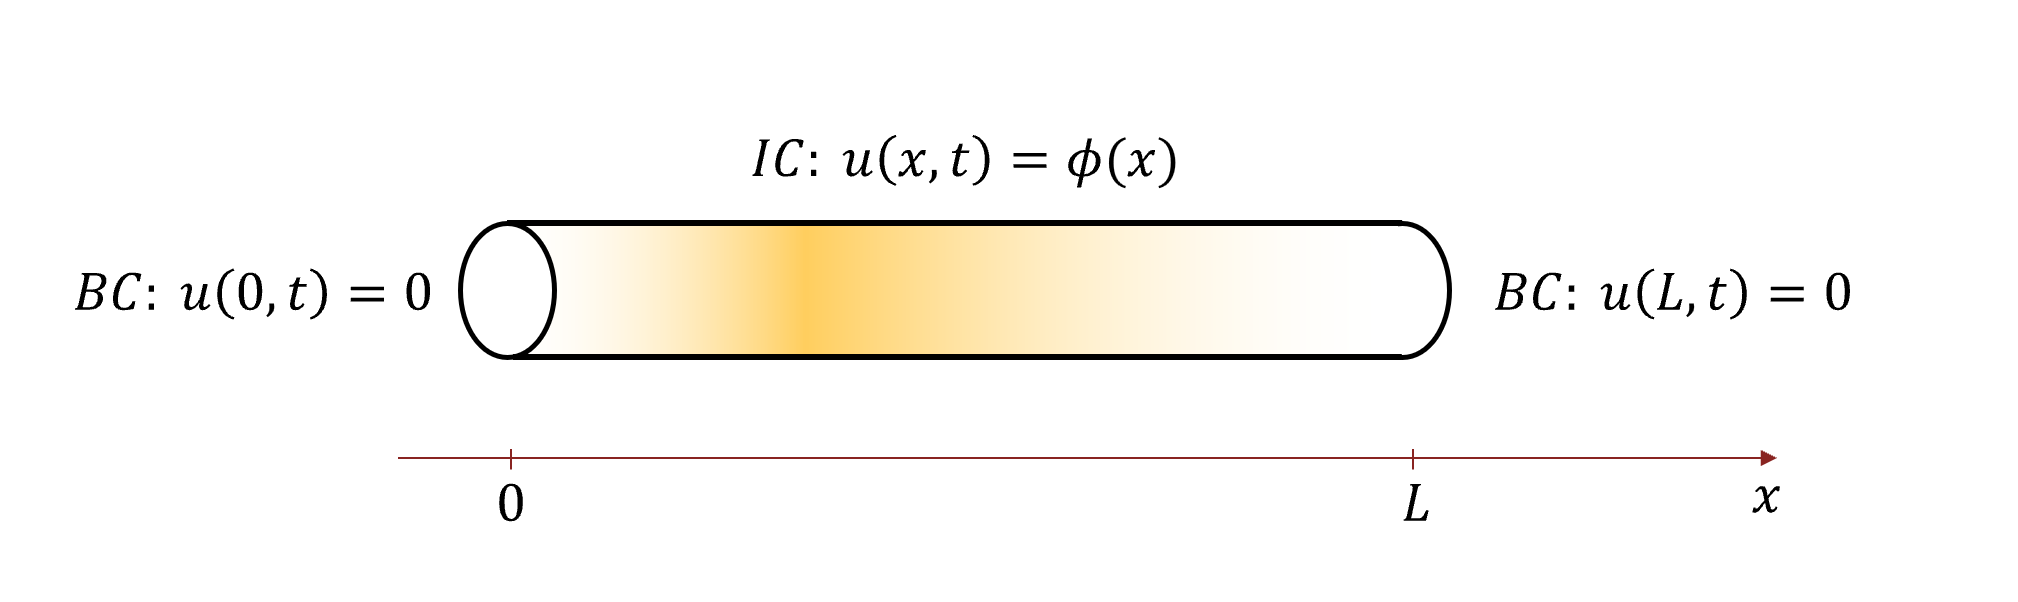

### Challenges

- Understand the Heat Equation model and get deeper insight of the **heat solution structure**

- Understand different **thermal behaviors: **materials can either **store the heat** (and heat up quickly) or **transfer the heat** (don't heat up or heat up very slowly)

- Explore the impact of **different materials**, and **different initial conditions, even with wild jumps**

### Solution

- Heat irreversibly flows from hot to cold until reaching a stationary equilibrium (zero in this case). 

- **Discover the heat structure **by using analytical methods, eg separation of variables and Fourier's analysis. **Transient temperature exponentially decays to zero, the time decay depending on the material (thermal diffusivity). **Any initial "jump" is smoothed out.

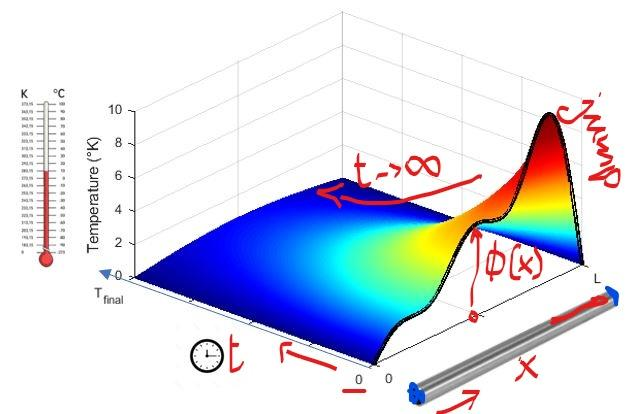

- Materials with **large diffusivity** (carbon, pyrolytic graphite, ..) can transfer heat fast without storing it, this means they don't heat up. So they can be "better" for some applications, eg semiconductors, electronics, nanomaterials, diamond nanowires, etc. 

## Key facts 

### The great Fourier's ideas

            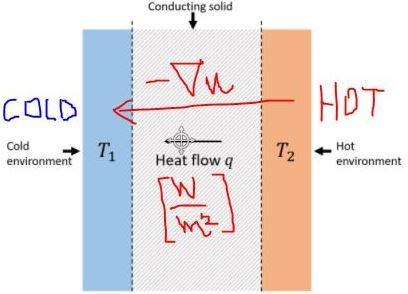          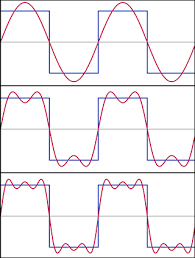

[Joseph Fourier](https://en.wikipedia.org/wiki/Joseph_Fourier) (1768 – 1830) demonstrated his ideas on heat diffusion in his famous treatise *Théorie analytique de la chaleur*, published in 1822:

- [Fourier's Analysis](https://en.wikipedia.org/wiki/Fourier_analysis#:~:text=In%20mathematics%2C%20Fourier%20analysis%20(%2F,sums%20of%20simpler%20trigonometric%20functions.)**:** every function, even with jumps, can be represented as **"sum of harmonics**". He applied this idea to represent the given initial temperature $\phi \left(x\right)$ along the rod. See details here


$$\phi \left(x\right)=\sum_{n=1}^{\infty \;} b_n \cdot \sin \left(\frac{n\pi \;}{L}x\right)\;$$
   
$$x\in \left(0,L\right)$$
 

- [Fourier's Law ](https://en.wikipedia.org/wiki/Thermal_conduction#Fourier's_law)of heat conduction: heat flows irreversibly **from higher to lower **temperature: 

$q=-\;k\;\frac{\partial u}{\partial x}\left(x,t\right)$   where $\;\mathit{\mathbf{k}}=$[*conductivity*](https://en.wikipedia.org/wiki/Thermal_conductivity_and_resistivity)  $\left\lbrack \frac{W}{m\cdot \textrm{°K}}\right\rbrack \;$ 

- [Heat Equation](https://en.wikipedia.org/wiki/Heat_equation#Solving_the_heat_equation_using_Fourier_series) follows from Fourier's Law, Laws of Thermodynamics and Conservation of Energy  and can be solved by adding initial condition (IC) and boundary conditions (BC). When BC are homogeneous ($\left.\textrm{eg}\ldotp \;0\textrm{°K}\right)\;$, the solution is transient decaying to zero as time increases. 

    $\left\lbrace \begin{array}{ll}
\frac{\;\partial \;u}{\partial \;t}\left(x,t\right)=\mathit{\mathbf{D}}\;\frac{\;\partial {\;}^2 u}{\partial \;x^2 }\left(x,t\right) & \\
+\;\textrm{IC}+\textrm{BC}\;\left(\textrm{homogeneous}\right) & 
\end{array}\right.\;\;$    where $\mathit{\mathbf{D}}=\;$[diffusivity](https://en.wikipedia.org/wiki/Thermal_diffusivity) $\left\lbrack \frac{m^2 }{s}\right\rbrack$

- **Meaning of Diffusivity vs conductivity:** conductivity tells only about heat transfer rate; diffusivity tells also the effect on the temperature change due to the heat transfer. Materials with **large diffusivity** can **transfer heat fast **(large $k$**) without or slowly heating up **(**have low heat capacity **$c_p$ and low density $\rho$, eg. "don't store heat", but use heat to trigger a new temp grad$\nabla u$ and make the thermal wave propagate). We'll simulate with different material diffusivity. 


$$\mathit{\mathbf{D}}=\frac{\;\mathit{\mathbf{k}}}{{\mathit{\mathbf{c}}}_{\mathit{\mathbf{p}}} \cdot \rho \;}=\frac{\;\textrm{conducted}\;\textrm{heat}}{\textrm{stored}\;\textrm{heat}\;\left(\textrm{heating}\;\textrm{up}\right)}$$
 

- **Transient solution: **satisfies BC (0°K)** and **exponentially decays to 0 when $t\to \infty \;\;$with **a time decay **

$\tau =\frac{\;{\mathit{\mathbf{L}}}^2 }{\mathit{\mathbf{D}}}\;\;\;\;\;\left\lbrack s\right\rbrack$. 

            We'll see more details about transient structure here

[](https://en.wikipedia.org/wiki/Fourier_analysis#:~:text=In%20mathematics%2C%20Fourier%20analysis%20(%2F,sums%20of%20simpler%20trigonometric%20functions.)

#### Exercise: explore thermal diffusivity of different materials 

- Load `materials`.mat file with diffusivity values (in $\frac{{\textrm{mm}}^2 }{s}$) taken from [Diffusivity](https://en.wikipedia.org/wiki/Thermal_diffusivity) website

- Create a `dictionary` to associate the material name to the corresponding diffusivity value. 

- Create a UI Control (Drop Down) to quickly choose the material. 

load materials.mat materials  % Load the table 
materials

materials = 46×2 table
                     Name                      Diffusivity
    _______________________________________    ___________

    "Pyrolytic-graphite-parallel-to-layers"        1220   
    "Carbon/carbon-composite-at-25-°C"            216.5   
    "Helium-(300-K-1-atm)"                          190   
    "Silver-pure-(99.9%)"                        165.63   
    "Hydrogen-(300-K-1-atm)"                        160   
    "Gold"                                          127   
    "Copper-at-25-°C"                               111   
    "Aluminium"                                      97   
    "Silicon"                                        88   
    "Al-10Si-Mn-Mg-(Silafont-36)-at-20-°C"         74.2   
    "Aluminium-6061-T6-Alloy"                        64   
    "Molybdenum-(99.95%)-at-25-°C"                 54.3   
    "Al-5Mg-2Si-Mn-(Magsimal-59)-at-20-°C"           44   
    "Tin"              


% Use the table variables to build a dictionary <material name> --> <diffusivity> 
% Note: dictionary is recommended over containers.Map (since R2022b)
% DIFFUSIVITY_map = containers.Map(materials.Name, materials.Diffusivity); % old way
DIFFUSIVITY = dictionary(materials.Name, materials.Diffusivity);

D_iron = DIFFUSIVITY("Iron")

D_iron = 23

% Pick any material and check its diffusivity (in mm^2/s) 
material = "Aluminium";
D = DIFFUSIVITY(material)

D = 97


save materials.mat DIFFUSIVITY -append

### Where the Heat Equation comes from

In $3$-dim space ($x\in \Re^3$, volume $V\subset \Re^3$, with 2-dim boundary surface $\partial V$), the main quantities involved and corresponding units of measurement are:                               

- 
$$u\left(x,t\right)\;\;\;\;\left\lbrack \textrm{°K}\right\rbrack \;\;=\textrm{Absolute}\;\textrm{Temperature}\;\textrm{at}\;\textrm{point}\;x\;\textrm{at}\;\textrm{time}\;t\;\;$$


- $Q\left(x,t\right)\;\;\left\lbrack \frac{J}{m^3 }\right\rbrack \;=\textrm{Heat}\;\textrm{Energy}\;\textrm{per}\;\textrm{volume}\;\textrm{unit}$, so $\int_V Q\left(x,t\right)\;\textrm{dx}=\textrm{internal}\;\textrm{Heat}\;\textrm{Energy}\;\left\lbrack J\right\rbrack \;\textrm{in}\;V\;\;$  

- $\vec{q} \left(x,t\right)\;\left\lbrack \frac{W}{m^2 }\right\rbrack =\;\textrm{Heat}\;\textrm{Flux}\;\textrm{through}\;\textrm{surface}\;\textrm{unit}$, so$-\oint_{\partial V} \vec{q} \cdot {\vec{\nu} }_{\textrm{out}} \;d\sigma =\textrm{incoming}\;\textrm{Heat}\;\textrm{Flux}\;\left\lbrack W\right\rbrack \;\textrm{through}\;\partial V$ 

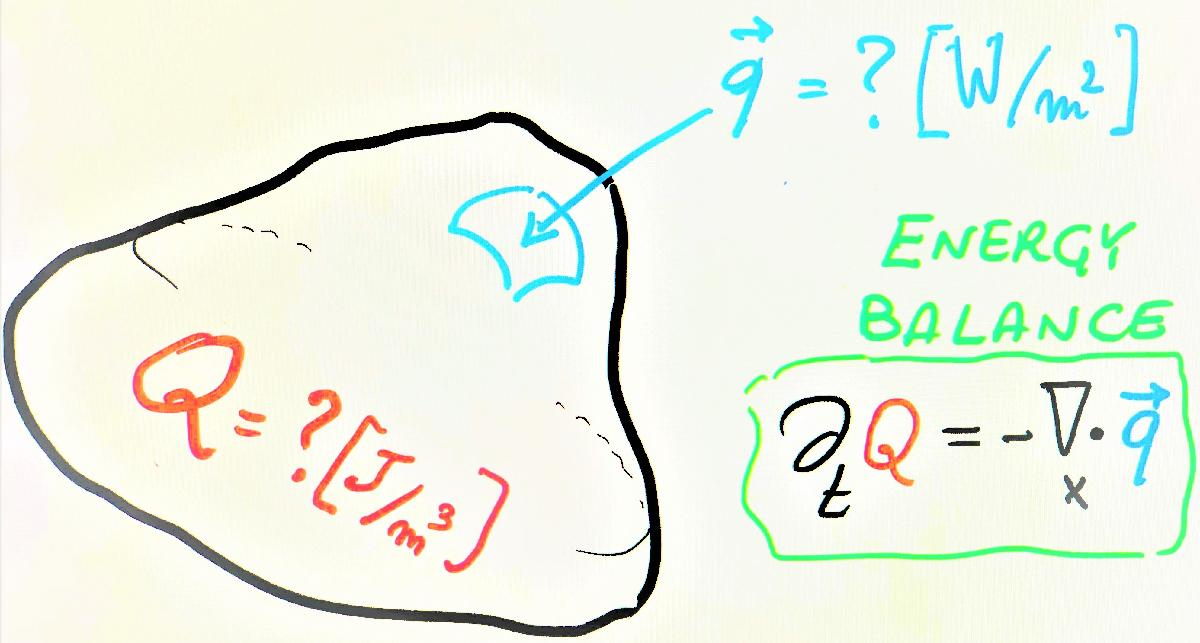

**Energy Balance**


$$\frac{\partial }{\partial t}\int_V Q\left(x,t\right)\;\textrm{dx}=-\oint_{\partial V} \vec{q} \cdot {\vec{\nu} }_{\textrm{out}} \;d\sigma \;\overset{\;\textrm{Gauss}}{\;=} -\int_V \nabla_x \cdot \vec{q} \;\textrm{dx}$$
      
$$\left\lbrack W\right\rbrack$$


or, equivalently, in differential form: : 


$$\partial_{t\;} Q=-\nabla_x \cdot \vec{q}$$
                
$$\left\lbrack \frac{W}{m^3 }\right\rbrack$$


Recall: $\nabla_x \cdot \vec{q} =\textrm{divergence}\left(\vec{q} \right)=\frac{\;\partial q_1 }{\partial x_1 }+\frac{\;\partial q_2 }{\partial x_2 }+\frac{\;\partial q_3 }{\partial x_3 }$.

**Constitutive Laws** 

- $Q=c_p \;\rho \;u$        **(****Thermodynamics****),**  with [*specific heat capacity*](https://en.wikipedia.org/wiki/Specific_heat_capacity) $c_p \;\left\lbrack \frac{J}{\textrm{kg}\cdot \textrm{°K}}\right\rbrack$

- $\vec{q} =-\;k\;\nabla u$   **  (****Fourier's Law****), **        with [*conductivity*](https://en.wikipedia.org/wiki/Thermal_conductivity_and_resistivity) $k\;\left\lbrack \frac{W}{m\cdot \textrm{°K}}\right\rbrack$

By combining the energy balance with the two constitutive laws above, we get the fundamental 

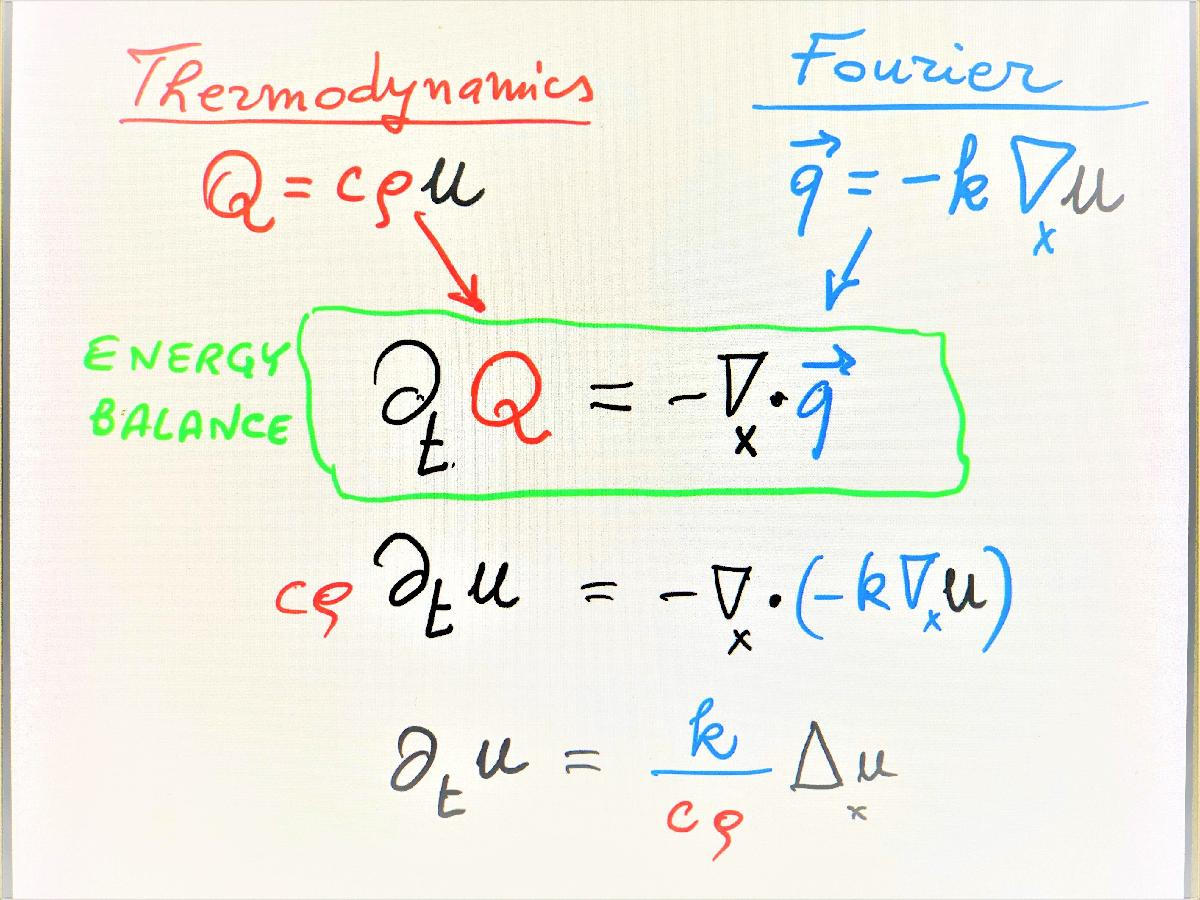        

$\Longrightarrow \;\;\;\;\;\;\;\;\;\;\;\;\;\frac{\partial u}{\partial t}\;=D\;\;\Delta u\;$          **Heat Equation **with [diffusivity](https://en.wikipedia.org/wiki/Thermal_diffusivity) $D:=\frac{\;k}{c_p \cdot \rho \;}$ $\left\lbrack \frac{\;m^2 }{s}\right\rbrack$.

Recall:  $\nabla u=\textrm{grad}\left(u\right)=\left\lbrack \frac{\;\partial u}{\partial x_1 },\;\frac{\;\partial u}{\partial x_2 },\frac{\;\partial u}{\partial x_3 }\right\rbrack$,  $\Delta u=\nabla \cdot \;\left(\nabla u\right)=\textrm{Laplacian}\left(u\right)=\frac{\;\partial^2 u}{\partial x_1^2 }+\frac{\;\partial^2 u}{\partial x_2^2 }+\frac{\;\partial^2 u}{\partial x_3^2 }$. 

In $1$-dim, we have $\nabla \cdot \vec{q} =\frac{\;\partial q}{\partial x}$, $\nabla u$=$\frac{\;\partial u}{\partial x}$  and $\Delta u$= $\frac{\partial^2 u}{\partial x^2 }$.

#### Exercise: derive heat equation in 1-dim case.

Use the equations above in order (in the order RGB :-) 


$$\frac{\partial u}{\partial t}\;\;\overset{\overset{\textrm{RED}}{\;\textrm{Thermodynamics}} }{=} \;\frac{\;1}{c_p \;\rho \;}\frac{\partial }{\partial t}\;?\;\;\;\;\;\;\;\;\;\;\;\;\overset{\overset{\textrm{GREEN}}{\;\textrm{Energy}\;\textrm{Balance}} }{=\;} \;\frac{\;1}{c_p \;\rho \;}\left(-\frac{\;\partial }{\partial x}\;?\right)\;\;\;\;\;\;\overset{\overset{\textrm{BLUE}}{{\textrm{Fourier}}^{\prime } s\;\textrm{law}} }{=} \;\frac{\;1}{c_p \;\rho \;}\;\left(-\frac{\;\partial }{\partial x}\;\left(?\;\frac{\;\partial \;}{\partial x}\;?\;\;\right)\right)=\;\;\frac{\;?}{c_p \;\rho \;}\;\frac{\partial^2 }{\partial x^2 }\;?=\;?\;\frac{\partial^2 }{\partial x^2 }\;?$$
    

*Solution: *


$$\frac{\partial u}{\partial t}\;\;\overset{\overset{\textrm{RED}}{\;\textrm{Thermodynamics}} }{=} \frac{\;1}{c_p \;\rho \;}\frac{\partial }{\partial t}\;Q\;\;\;\;\;\;\;\;\;\;\;\overset{\overset{\textrm{GREEN}}{\;\textrm{Energy}\;\textrm{Balance}} }{=\;} \frac{\;1}{c_p \;\rho \;}\left(-\frac{\;\partial }{\partial x}q\right)\;\;\;\;\;\;\;\;\;\;\;\overset{\overset{\textrm{BLUE}}{{\textrm{Fourier}}^{\prime } s\;\textrm{law}} }{=} \;\frac{1\;}{c_p \;\rho \;}\left(-\frac{\;\partial }{\partial x\;}\;\left(-k\;\frac{\;\partial u}{\partial x}\;\right)\right)=\frac{\;k}{c_p \cdot \rho \;}\;\frac{\partial^2 u}{\partial x^2 }=D\;\frac{\partial^2 u}{\partial x^2 }$$


#### Exercise: Using symbolic variables to assign units and check consistency

Exercise Part 1: use Symbolic variables and `symunit` from Symbolic Math Toolbox™ to assign units

syms t x u(x,t) q(x,t) Q(x,t) c k rho D
whos t x u

  Name      Size            Bytes  Class     Attributes

  t         1x1                 8  sym                 
  u         1x1                 8  symfun              
  x         1x1                 8  sym                 



unit = symunit; % first, load to package to use the units
t = t * unit.s % seconds

$$t = t\,s$$

x = x * unit.m % meter

$$x = x\,m$$

u = u * unit.K % Kelvin

$$u(x, t) = u\left(x,t\right)\,K$$


Q = Q * unit.joule/unit.m^3 % heat energy [J/m^3]

$$Q(x, t) = Q\left(x,t\right)\,\frac{J}{m^{3}}$$

q = q * unit.W/unit.m^2       % heat flux (W/m^2)

$$q(x, t) = q\left(x,t\right)\,\frac{W}{m^{2}}$$

rho = rho * unit.kg/unit.m^3;  % density [kg/m^3]
c = c * unit.J/(unit.kg*unit.K); % specific heat capacity [J/(kg*K)]


Exercise: Complete for conductivity $k\;$and diffusivity $D=\frac{\;k}{c_p \cdot \rho \;}$

% k = ...   % conductivity [W/(m*K)]
% D = ...   % diffusivity (use definition)


*Solution*

k = k * unit.W/(unit.m*unit.K) % conductivity [W/(m*K)]

$$k = k\,\frac{W}{K\,m}$$

D = simplify(k/(c*rho))   % diffusivity [m^2/s]

$$D = \frac{k}{c\,\rho }\,\frac{m^{2}}{s}$$

You can compute derivative using `diff `**function **and define equation using` ==. `For example:

- $\frac{\partial Q}{\partial t}$ $=-\frac{\;\partial q}{\partial x}$     (Energy balance)

EnergyConservation = diff(Q,t) == -diff(q,x);
EnergyConservation = unitConvert(EnergyConservation, unit.W)

$$EnergyConservation(x, t) = \frac{\partial }{\partial t}Q\left(x,t\right)\,\frac{W}{m^{3}}=-\frac{\partial }{\partial x}q\left(x,t\right)\,\frac{W}{m^{3}}$$

Exercise Part 2:  Write 1-dim equations and check units consistency of each equations:

- $Q\;=c_p \;\rho \;u$     (Thermodynamics)

- $q\;=-k\frac{\;\partial u}{\partial x}$     (Fourier's Law)

- $\frac{\partial u}{\partial t}=D\;\frac{\;\partial^2 u}{\partial x^{2\;} }$   (Heat Equation)

%% Write your solution



*Solution*

Thermodynamics = Q == c*rho*u

$$Thermodynamics(x, t) = Q\left(x,t\right)\,\frac{J}{m^{3}}=c\,\rho \,u\left(x,t\right)\,\frac{J}{m^{3}}$$

Thermodynamics_dT  = diff(Q,t) ==  c*rho*diff(u,t)

$$Thermodynamics\_dT(x, t) = \frac{\partial }{\partial t}Q\left(x,t\right)\,\frac{J}{m^{3}\,s}=c\,\rho \,\frac{\partial }{\partial t}u\left(x,t\right)\,\frac{J}{m^{3}\,s}$$


FourierLaw = q == -k*diff(u,x)    % are units ok?

$$FourierLaw(x, t) = q\left(x,t\right)\,\frac{W}{m^{2}}=-k\,\frac{\partial }{\partial x}u\left(x,t\right)\,\frac{W}{m^{2}}$$


HeatEq = diff(u,t) == D*diff(u,x,x)

$$HeatEq(x, t) = \frac{\partial }{\partial t}u\left(x,t\right)\,\frac{K}{s}=\frac{k\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)}{c\,\rho }\,\frac{K}{s}$$

checkUnits(HeatEq)

ans = struct with fields:
    Consistent: 1
    Compatible: 1


## *************  PART II : SOLUTION  ********** ***

Review Table of Contents

## ***Solving Transient problem for Heat Equation***

We consider 1-dim rod, without any interaction (no heat exchange) with external environment. 

Inputs are: 

- $L>0$** length** of the rod, 

- $D>0$** diffusivity** of material and 

- the initial condition $\phi \left(x\right)$ 

$\left\lbrace \begin{array}{ll}
\;\frac{\partial u}{\partial t}\left(x,t\right)=D\;\frac{{\;\partial }^2 u}{\partial x^2 }\left(x,t\right) & x\in \left(0,L\right)\;,t>0\\
u\left(x,0\right)=\phi \left(x\right) & \forall \;x\in \left(0,L\right)\;\;\;\;\;\;\;\;\left(\textrm{IC}\;=\;\textrm{"Hot"}\;\textrm{Initial}\;\textrm{Condition}\right)\\
u\left(0,t\right)=u\left(L,t\right)=0\;, & \forall \;t>0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(\textrm{BC}=\;\textrm{"Cold"}\;\textrm{Boundary}\;\textrm{Conditions}\right)
\end{array}\right.$

The **transient problem** is characterized by **"homogeneous BC"**, eg, **hold boundaries at the same fixed temperature **$0\textrm{°K}$. So "hot" IC will diffuse until reaching a stationary equilibrium, which is $0\textrm{°K}\;$, as there is no thermal gradient between boundaries.   

Note: many other "non-homogeneous" problems could be solved and a topic for other lectures.  

### The structure of Heat solution 

Heat Solution has the following "separated" space-time structure: 

$u\left(x,t\right)=\sum_{n=1}^{\infty \;} b_n \cdot \sin \left(\lambda_n \;x\right)\;\cdot e^{-{\;t\;D\;\;\lambda_n }^2 } \;\;$,      with $\lambda_{n\;} =\frac{n\;\pi \;}{L}$ 

The transient heat solution enjoy some key features:

- **"SIN IN SPACE, EXP IN TIME**" (eigenvector of $\partial_{\textrm{xx}}^2$  and $\partial_t$ respectively)

- **time dilation is "the square" of space dilation**, and parabolic dilations $u\left(\alpha \;x,\alpha {\;}^{2\;} t\right)$are still solutions $\forall \;\alpha >0$

- **homogeneous BCs are "embedded"**, eg $u\left(0,t\right)=u\left(L,t\right)=0\;$are satisfied $\forall \;b_{n\;}$

- **its coefficients **$b_n$** are constant (depending on IC),** so the transient solution will **decay to zero as **$t\to \infty \ldotp \;$

Go back to Key Facts

#### Visualizing heat structure with animation

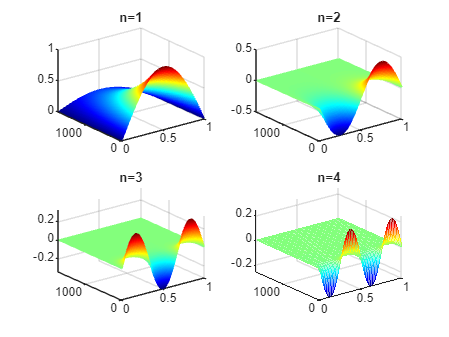

D = 97*1e-6; % aluminium diffusivity [m^2/s]
L = 1;       % rod length [m]
Tfinal = 1800; % final time [s] % 30 min = 1800 s

b = @(n) (-1)^(n+1)/n;
lambda = @(n) n*pi/L;
u_n =  @(x,t,n) b(n) .* sin(x*lambda(n)) .* exp(-t*D*lambda(n).^2);

close all
figure
colormap jet
for n = 1:4
    subplot(2,2,n)
    fsurf(@(x,t) u_n(x,t,n), [0 L 0 Tfinal], "EdgeColor","interp")
    hold on
    title("n="+n)
    drawnow
end
alpha(0.5)

Animation to understand the heat structure as a "sum":

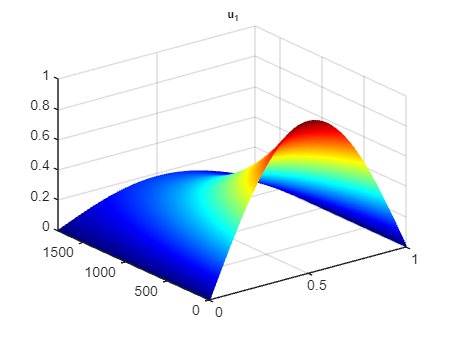

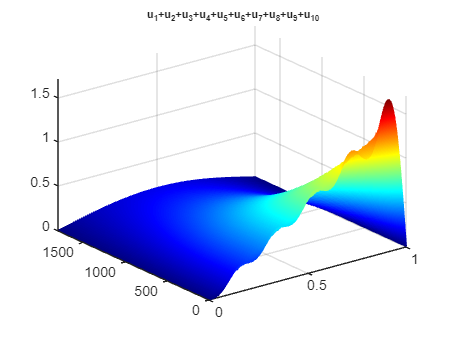

N = 10;
hf =figure;
colormap jet
str = "";
uStruct = @(x,t) 0;
for n = 1:N
    uStruct = @(x,t) uStruct(x,t) +  u_n(x,t,n);
    fsurf(gca, uStruct, [0 L 0 Tfinal], "EdgeColor","interp")
    if n ==1, str="u_1";else str = str+"+u_{"+n+"}"; end
    title(str, FontSize=8)
    drawnow
end

#### Using Symbolic variables to create a general heat structure 

Let's use symbolic variables and symbolic functions, also to define the heat structure:

syms t x n b_n L D  lambda(n) u_n(x,t,n)
assume(n, "integer")
assume([L D], "positive")
lambda(n) = n*pi/L;
u_n(x,t,n) =  b_n .* sin(x*lambda(n)) .* exp(-t*D*lambda(n).^2) ;

whos t x lambda u_n 

  Name        Size            Bytes  Class     Attributes

  lambda      1x1                 8  symfun              
  t           1x1                 8  sym                 
  u_n         1x1                 8  symfun              
  x           1x1                 8  sym                 



We'd better **refactor the previous code with a local function** to quickly build symbolic function object for the heat structure:

Scroll down to insert a local function

myheat   = buildHeatStruct

$$myheat(x, t, n) = b_{n}\,{\mathrm{e}}^{-\frac{\text{D}\,n^{2}\,t\,\pi^{2}}{L^{2}}}\,\sin\left(\frac{\pi \,n\,x}{L}\right)$$

#### Using SUBS to embed expressions and values

You can then easily substitute expression $b_n =\frac{1}{n}$ or fix numerical values $n=3,L\;=1,\;D=97\cdot \;{10}^{-6}$ and then visualize:

syms L
subs(myheat, L , 5)

$$ans(x, t, n) = b_{n}\,\sin\left(\frac{\pi \,n\,x}{5}\right)\,{\mathrm{e}}^{-\frac{\text{D}\,n^{2}\,t\,\pi^{2}}{25}}$$


L = 1; % length of the rod
D = 97e-6; % diffusivity of alluminium (m^2/s)
b_n = 1/n; % some initial condition

u0(x,t,n) = subs(myheat, sym(["L" "D" "b_n"]), [L D b_n])

$$u0(x, t, n) = \frac{\sin\left(\pi \,n\,x\right)\,{\mathrm{e}}^{-\frac{3578668350299653\,n^{2}\,t\,\pi^{2}}{36893488147419103232}}}{n}$$


u3(x,t) = u0(x,t, 3) % for example, set n = 3

$$u3(x, t) = \frac{{\mathrm{e}}^{-\frac{32208015152696877\,t\,\pi^{2}}{36893488147419103232}}\,\sin\left(3\,\pi \,x\right)}{3}$$

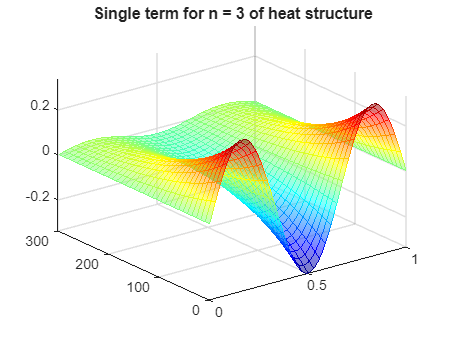


Tfinal = 300; % [s]  % about 5 minutes
figure
fsurf(u3, [0 L 0 Tfinal], "EdgeColor","interp"), colormap jet
title("Single term for n = 3 of heat structure")
alpha(0.5)

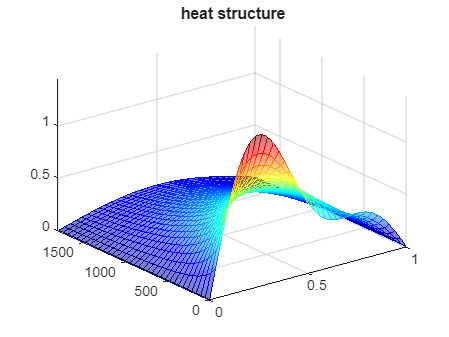


heat3(x,t) = u0(x,t, 1) + u0(x,t, 2) + u0(x,t, 3);
Tfinal =1800; % [s]  % about 30 minutes
figure
fsurf(heat3, [0 L 0 Tfinal], "EdgeColor","interp"), colormap jet
title("heat structure")
alpha(0.5)

### Understanding the analytical tricks to get the "why" of heat structure 

We demonstrate that heat structure $\sum_{n=1}^{\infty \;} b_n \cdot \sin \left(\lambda_n \;x\right)\;\cdot e^{-{\;t\;D\;\;\lambda_n }^2 } \;\;$is actually

- **"A" solution** of Heat Equation

- **"THE" solution**, eg. solutions must have that structure necessarily. 

Live Script can help 

- **UNDERSTAND where the structure of heat solution come from. **

- **RUN AND VERIFY **analytical methods (separation of variables, ODE, Fourier Analysis,..)

**Exercise: VERIFY that the heat structure satisfies Heat Equation **

Reload the heat structure (using local function built before)  and then compute derivatives

syms t x D
u = buildHeatStruct

$$u(x, t, n) = b_{n}\,{\mathrm{e}}^{-\frac{\text{D}\,n^{2}\,t\,\pi^{2}}{L^{2}}}\,\sin\left(\frac{\pi \,n\,x}{L}\right)$$

ut = diff(u,t)

$$ut(x, t, n) = -\frac{\text{D}\,b_{n}\,n^{2}\,\pi^{2}\,{\mathrm{e}}^{-\frac{\text{D}\,n^{2}\,t\,\pi^{2}}{L^{2}}}\,\sin\left(\frac{\pi \,n\,x}{L}\right)}{L^{2}}$$

uxx = diff(u, x, 2)

$$uxx(x, t, n) = -\frac{b_{n}\,n^{2}\,\pi^{2}\,{\mathrm{e}}^{-\frac{\text{D}\,n^{2}\,t\,\pi^{2}}{L^{2}}}\,\sin\left(\frac{\pi \,n\,x}{L}\right)}{L^{2}}$$

what_is_different = ut/uxx

$$what\_is\_different(x, t, n) = \text{D}$$

**Look for a solution "in the dark"**

Forget any heat structure. How can we find a solution for Heat Equation problem? 

 $u\left(x,t\right)=\;???$   to satisfy    $\underset{\underset{\left(\textrm{Heat}\;\textrm{Structure}\;\textrm{with}\;\textrm{BC}\;\textrm{embedded}\right)}{\overset{\textrm{STEP}\;1}{\textrm{Separation}\;\textrm{of}\;\textrm{variables}} } }{\underbrace{\frac{\partial u}{\partial t}\left(x,t\right)=D\;\frac{{\;\partial }^2 u}{\partial x^2 }\left(x,t\right)\;\;+\;\;\;\;\textrm{BC}} }$   + $\underset{\underset{{\textrm{FOURIER}}^{\prime } \mathit{\mathbf{s}}\;\textrm{Analysis}}{\textrm{STEP}\;2} }{\underbrace{\textrm{IC}} }$

syms   x t u(x,t) L D n b_n
assume([L D], "positive")
% Heat Equation
HeatEq = diff(u,t) == D *diff(u,x,2)

$$HeatEq(x, t) = \frac{\partial }{\partial t}u\left(x,t\right)=\text{D}\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)$$


% Boundary conditions (used in Step 1: Separation of variables)
BC_0 = u(0,t) == 0

$$BC\_0 = u\left(0,t\right)=0$$

BC_L = u(L,t) == 0

$$BC\_L = u\left(L,t\right)=0$$


% Initial condition (used in Step 2: Fourier's Analysis)
phi(x) = x; % or any other function of x

#### Step 1: Separation of variables


$$\underset{\overset{\textrm{STEP}\;1}{\textrm{Separation}\;\textrm{of}\;\textrm{variables}} }{\underbrace{\frac{\partial u}{\partial t}\left(x,t\right)=D\;\frac{{\;\partial }^2 u}{\partial x^2 }\left(x,t\right)\;\;+\;\;\;\;\textrm{BC}:u\left(0,t\right)=u\left(L,t\right)=0} }$$


$\textrm{SEPARATION}\;\textrm{of}\;\textrm{variables}\;$$\textrm{means}\;u\left(x,t\right)=X\left(x\right)\cdot \;T\left(t\right)$. So

$X\left(x\right)\;$$\frac{d}{\mathrm{d}t}T\left(t\right)=D\;\;T\left(t\right)\frac{{\mathrm{d}}^2 }{\mathrm{d}x^2 }X\left(x\right)$  +  $\textrm{BC}:\;X\left(0\right)=0=X\left(L\right)$

% Separate variables in the Heat Equation
syms  T(t) X(x)
SepVar = subs(HeatEq, u(x,t), X(x)*T(t))

$$SepVar(x, t) = X\left(x\right)\,\frac{\partial }{\partial t}T\left(t\right)=\text{D}\,T\left(t\right)\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)$$


% Separate variables in BC
BCX_0 = subs(BC_0, u(0,t), X(0)*T(t))/T(t)

$$BCX\_0 = X\left(0\right)=0$$

BCX_L = subs(BC_L, u(L,t), X(L)*T(t))/T(t)

$$BCX\_L = X\left(L\right)=0$$

$\textrm{SEPARATION}\;\textrm{of}\;\textrm{equation}\;\textrm{means}:$ $t\;$on the left side, $x$ on the right side


$$\frac{\frac{d}{\mathrm{d}t}T\left(t\right)}{D\cdot T\left(t\right)}\;=\;\;\frac{\;\frac{{\mathrm{d}}^2 }{\mathrm{d}x^2 }X\left(x\right)}{X\left(x\right)}\;=C=-\lambda^2$$
       
$$\forall \;x,\forall \;t$$
   

% Separate the equation further
SepVar = SepVar/(D*X(x)*T(t))

$$SepVar(x, t) = \frac{\frac{\partial }{\partial t}T\left(t\right)}{\text{D}\,T\left(t\right)}=\frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}$$

For the 2 sides to be equal $\forall \;x,\forall \;t$ , they MUST BE constant $C$. To avoid trivial solutions, it must be $C<0$, so it is convenient to **put **$C=-\lambda^2 \;$.

So we can **separate into two ****ODEs **(eigenvalue problems):

- $1^{\textrm{st}\;} \textrm{order}\;$**ODE for time:  **   $\frac{\;\dot{\;T} \left(t\right)}{D\cdot T\left(t\right)}={-\lambda }^{2\;} \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Longrightarrow \;{\;\;\;\;T\left(t\right)=C_{1\;} e}^{-t\;D{\;\lambda }^2 }$      $\forall \;\lambda >0$

- $2^{\textrm{nd}\;} \textrm{order}\;$**ODE for space**:  $\frac{\;\ddot{X} \left(x\right)}{X\left(x\right)}=-{\;\lambda }^{2\;}$    + $\underset{\textrm{left}\;\;\textrm{BC}\;}{\underbrace{\;X\left(0\right)=0} } \;\;\;\;\Longrightarrow \;\;$ $X\left(x\right)=C_{2\;} \;\sin \left(\lambda \;x\right)$  

% Separate ODEs introducing constant -lambda^2
var = children(SepVar);
syms lambda
assume(lambda, "positive")
eqT = var{1} == -lambda^2

$$eqT = \frac{\frac{\partial }{\partial t}T\left(t\right)}{\text{D}\,T\left(t\right)}=-\lambda^{2}$$

eqX = var{2} == -lambda^2

$$eqX = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$


% Solve ODEs
T(t,lambda) = dsolve(eqT)        % 1-order eq for T(t)

$$T(t, lambda) = C_{1}\,{\mathrm{e}}^{-\text{D}\,\lambda^{2}\,t}$$

X(x,lambda) = dsolve(eqX, BCX_0); % 2-ord eq for X(t), using X(0)= 0
% Replace constant in X
constantX = setdiff(symvar(X(x,lambda)),sym(['C',x,lambda]));
X(x,lambda) = subs(-X(x,lambda), constantX, sym('C2'))

$$X(x, lambda) = C_{2}\,\sin\left(\lambda \,x\right)$$

**Can we take any **$\lambda ?$ Well.. no, because **right boundary condition** at $x=L$ will force ... 


$$\underset{\textrm{right}\;\textrm{BC}}{\underbrace{\;X\left(L\right)=0} } \;\;\;\;\Longrightarrow \;\;\;\;\sin \left(\lambda \;L\right)\;=0\;\;\;{\Longrightarrow \;\;\;\lambda }_n =\frac{n\;\pi \;}{\mathit{\mathbf{L}}}\;\forall n\in Z\;$$


% Solve right boundary condition wrt lambda: X(L,lambda) = 0, lambda = ??
[lambdaL,parameters, conditions] = solve(X(L,lambda) == 0, lambda, "ReturnConditions",true);
% Add an arbitrary multiplier (replace k with n)
n = sym("n", ["integer", "positive"]);
lambdaL = subs(lambdaL, parameters ,n)

$$lambdaL = \frac{\pi \,n}{L}$$

**Back to solution structure **$u_n \left(x,t\right)=b_n {\;X}_n \left(x\right)\cdot T_n \left(t\right)$

% Replace lambda = n*pi/L and rename constant C2 as b_n
syms b_n uStruct(x,t,n)
expT(t,n) = subs(T(t,lambda), [lambda sym('C1')], [lambdaL sym('1')]);
sinX(x,n) = subs(X(x,lambda), [lambda, sym('C2')],[lambdaL, b_n]);

% Back to product solution
uStruct(x,t,n) = collect(sinX(x,n) * expT(t,n), ["sin" "exp"])

$$uStruct(x, t, n) = b_{n}\,{\mathrm{e}}^{-\frac{\text{D}\,n^{2}\,t\,\pi^{2}}{L^{2}}}\,\sin\left(\frac{\pi \,n\,x}{L}\right)$$


% From symbolic to function handle (optional)
% SinXExpTfun = matlabFunction(uStruct)

#### ***Step 2: Fourier Analysis***

The heat structure satisfies BCs for $\forall \;b_n$, but heat solution must **satisfy the initial condition too:**

at $t=0:\;\;\;\;\phi \left(x\right)\overset{\textrm{IC}}{=} \;u\left(x,\;t=0\right)\;=\;\;\sum_{n=1}^{\infty \;} b_n \cdot \sin \left(\lambda_n \;x\right)\;\cdot e^{\;0} ,\;$   for which $b_n ??$

 Do you remember the Key facts? What is **FOURIER ANALYSIS**?** The main idea is ****ORTHOGONALITY!!!!**

Just multiply each member by $e_m =\sin \left(\lambda_m \;x\right)$and take integral of product over $\left\lbrack 0,L\right\rbrack$. 


$$\int_0^L \phi \left(x\right)\cdot \;\sin \left(\lambda_m \;x\right)\;\textrm{dx}=\sum_{n=1}^{\infty \;} b_n \;\int_0^L \sin \left(\lambda_n \;x\right)\cdot \sin \left(\lambda_m \;x\right)\;\textrm{dx}=\overset{\overset{\textrm{DO}\;\textrm{YOU}\;\textrm{SEE}}{\textrm{ORTHOGONALITY}\;??} }{\;\ldotp \ldotp \ldotp }$$


**Exercise: prove** **orthogonality of sine functions,** ie. $e_n \bot e_m$ . We prove $\left\langle e_n ,e_m \right\rangle =\int_0^L e_m e_n =\frac{L}{2}\delta_{\textrm{nm}} \;=0\;\;\textrm{when}\;m\not= n$

syms x m n L
assume([m n], ["integer" "positive"]), assume(L, "positive"), assumeAlso(not(L==pi))
lambda(n) = n*pi/L;
e(n) = sin(lambda(n)*x)

$$e(n) = \sin\left(\frac{\pi \,n\,x}{L}\right)$$

check_orthogonality = int( e(n)*e(m), 0, L)

$$check\_orthogonality = \left\{ \begin{array}{cl} \frac{L}{2} & \text{ if }m=n\\ 0 & \text{ if }m\neq n \end{array}\right.$$


$$\overset{\overset{\textrm{NOW}\;I\;\textrm{SEE}}{\textrm{ORTHOGONALITY}} }{\;\ldotp \ldotp \ldotp } \;\;=\;\sum_{n=1}^{\infty \;} b_n \;\;\frac{L}{\;2\;}\delta {\;}_{\textrm{nm}} =\frac{L}{2}b_m$$
    

So **FOURIER solution is:** given initial condition $\phi \left(x\right)$, take heat structure with 


$${\mathit{\mathbf{b}}}_{\mathit{\mathbf{n}}} =\frac{2}{\mathit{\mathbf{L}}}\;\int_0^{\mathit{\mathbf{L}}\;} \phi \left(\mathit{\mathbf{x}}\right)\cdot \sin \;\left(\lambda_{\mathit{\mathbf{n}}} \;\mathit{\mathbf{x}}\right)\;\textrm{dx}$$


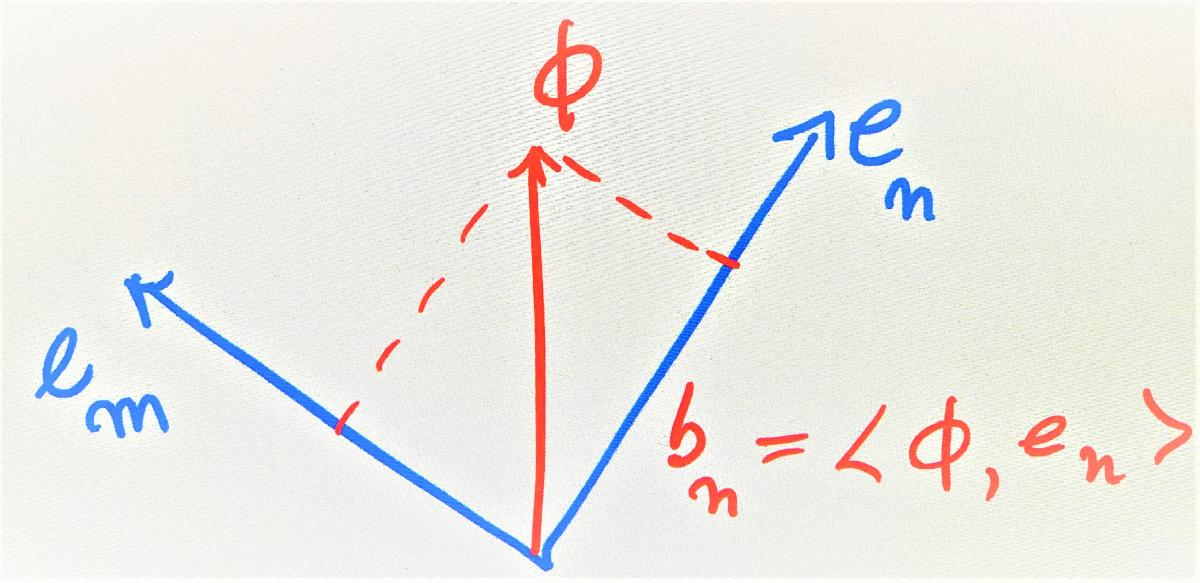

Note: if we "normalize" $e_n :=\sqrt{\frac{2}{L}}\sin \left(\lambda_n \;x\right)$ and define **inner product** $\left\langle u,v\right\rangle =\int_0^L u\left(x\right)v\left(x\right)\textrm{dx}$, we could say ${\left\lbrace e_n \right\rbrace }_{n=1,2,\ldotp \ldotp \ldotp }$is an orthonormal and dense set in the Hilbert space $L^2 \left(\left\lbrack 0,L\right\rbrack \right)$, so $\forall \;\phi \in L^2 \left(\left\lbrack 0,L\right\rbrack \right)\;$ $\phi =\sum_{n=1}^{\infty \;} b_n e_n$, with 

$b_n =\left\langle \phi ,e_n \right\rangle$     **(projection ****of **$\phi \;$**over **$\left.e_n \right)$  

**Computing Fourier's coefficients for IC **

syms x n b(n)
assume(n, ["integer", "positive"])
L = 1; % length of the rod [meter]

% Choose the Initial condition phi(x)
% phi(x) = L - x;
%% Examples:
% phi(x) = L-x;
phi(x) = piecewise(x<0.5, x, x>0.5, x-0.5);

% Compute Fourier coefficients of phi(x)
b(n) = simplify(2/L* int(phi(x) * sin(n*pi/L * x), 0, L))

$$b(n) = -\frac{{\left(-1\right)}^{n/2}\,{\left({\left(-1\right)}^{n/2}+1\right)}^{2}}{2\,n\,\pi }$$

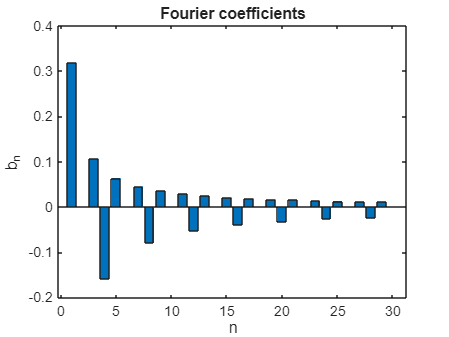


Nmax = 30;
% Visualize the coefficients
figure
bar(double(subs(b, n , 1:Nmax)))

xlabel("n")
ylabel("b_n")
title("Fourier coefficients")

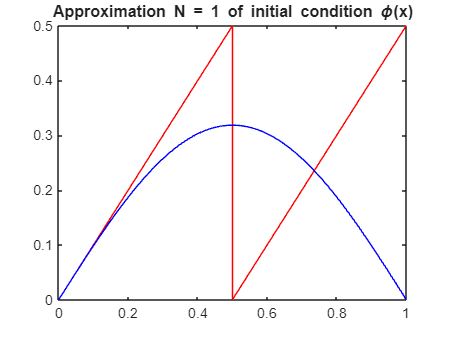


% Visualize approximation of initial condition
figure
for N = 1:Nmax
    fplot(phi, [0 L], "r")
    hold on
    
    IC = symsum(b(n) * sin(n*pi/L*x), n, 1, N);
    fplot(IC, [0 L], "b")
    
    title("Approximation N = " + N + " of initial condition \phi(x)")
    drawnow
    hold off
end

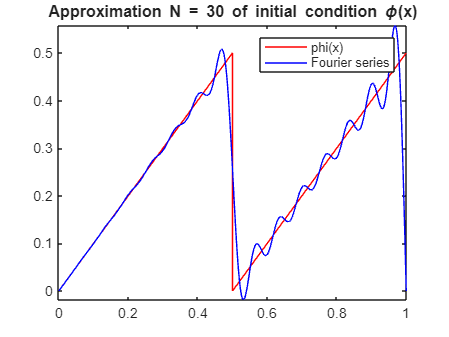

legend("phi(x)", "Fourier series")

**Embed ****Fourier coefficients**** into Heat structure to get solution**

Suppose to fix $L,\;D,\;N$ and $\phi \left(x\right)$: 

syms x t n b(n) phi(x)
assume(n, "integer")
L = 3; % length
phi(x) =  piecewise(x<L/2, x, x> L/2, L/2);  % IC
D = 23e-6;  % material (ex iron)
N = 30; % N terms for approximation

% A:Compute Fourier coefficients (as symbolic function) using phi(x) and L
b(n) = simplify(2/L*int( phi(x)* sin(n*pi/L*x) , 0, L))

$$b(n) = \frac{6\,n\,\pi \,{\sin\left(\frac{\pi \,n}{2}\right)}^{2}+6\,\sin\left(\frac{\pi \,n}{2}\right)-3\,\pi \,n}{n^{2}\,\pi^{2}}$$


% B: Build heat structure
heatStruct = buildHeatStruct

$$heatStruct(x, t, n) = b_{n}\,{\mathrm{e}}^{-\frac{\text{D}\,n^{2}\,t\,\pi^{2}}{L^{2}}}\,\sin\left(\frac{\pi \,n\,x}{L}\right)$$

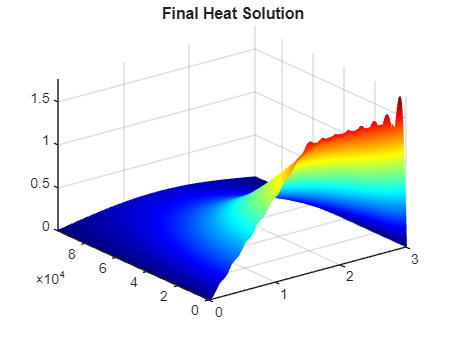


% C: Embedding b(n), L and D in the heat structure
heatStructEmb(x,t,n) = subs(heatStruct, sym(["b_n" "L" "D"]), [b L D]);

% D: Build solution by summing up N terms of the series
heatSolN = simplify(symsum(heatStructEmb, n, 1, N));

% Visualize
figure
colormap jet
tau = L^2/D; % [s]
fsurf(heatSolN,[0 L 0 tau/4], "EdgeColor","interp")
title("Final Heat Solution")

**Visualize animation of heat surface**

To speed up animation, we use numerical grids to discretize space and time and convert symbolic Fourier coefficients into numerical values. 

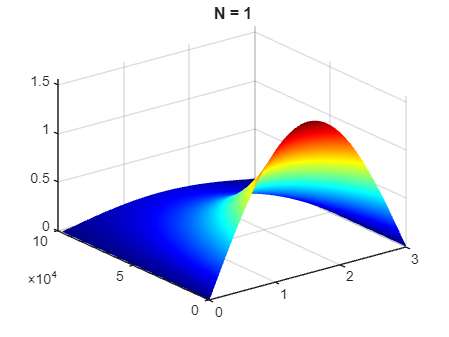

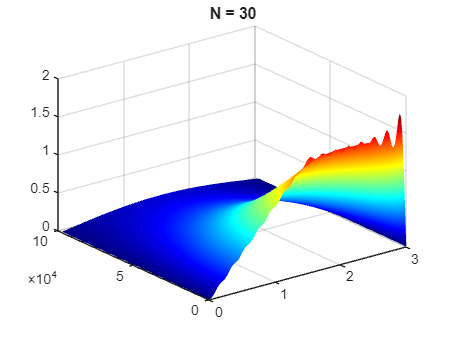

figure
colormap jet
N = 30;

% Define numerical grid for space and time
xResolution = 1000;
tResolution = 100;
xnum = linspace(0,L, xResolution);
tnum = linspace(0, tau/4, tResolution);
[XX, TT] = meshgrid(xnum, tnum);

% Convert Fourier coefficients to numerical values
bNum = double(subs(b, n, 1:N));

TEMP = zeros(size(XX));
for k = 1:N
    lambda_k = k*pi/L;
    % Define TEMPerature matrix and surf at each loop
    TEMP = TEMP +  bNum(k) * sin(lambda_k*XX) .* exp(-TT*D*(lambda_k)^2);
    surf(XX, TT, TEMP )
    title ("N = "+ k)
    shading interp
    drawnow 
end

### Simulation 

#### Prepare code for reusability

Prepare some reusable local function for quick computation and good visualization (go back to code)

material = "Iron";
L = 1;
syms x
phi(x) =  2*x;
N = 5;

Tfinal = 2;  
DHMS = "hours";

%% LOCAL FUNCTION REQUIREMENTS:
% The first 2 input arguments are mandatory to compute D and tau
% The first 4 input arguments are mandatory to compute heat solution
% 5th and 6th are mandatory to visualize: Tfinal+DHMS (Days,Hours,Minutes,Seconds)
% 7th input (is mandatory to see animation (any placeholder: 1,true, ...)

%% Testing code (and debug) before using it for final simulation
[~, D, tau] = buildHeatSol(material, L) % only computation 

D = 2.3000e-05

tau = 4.3478e+04

uN  = buildHeatSol(material, L, phi, N); % soluti
[~, D, tau, b] = buildHeatSol(material, L, phi, N, Tfinal, DHMS); % Viz. surface
b

$$b(n) = -\frac{4\,{\left(-1\right)}^{n}}{n\,\pi }$$

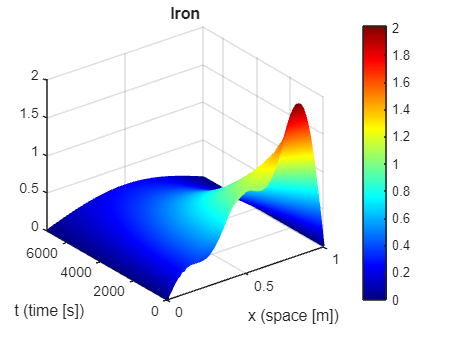

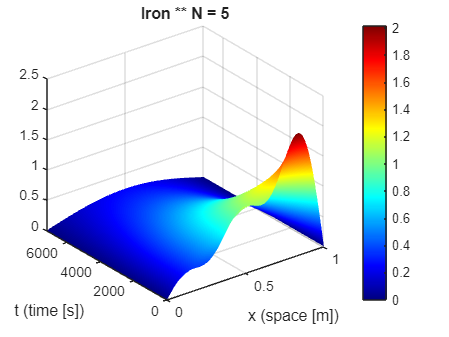

[~, D, tau] = buildHeatSol(material, L, phi, N, Tfinal,DHMS, 1); % Viz. animation

#### Using interactive controls to change parameters (HAVE FUN)

Change parameters, then click RUN button. Have fun!

%%%%%%%%%%%%% YOUR INPUT PARAMETERS %%%%%%%%%%%%% 
% Choose the material (diffusivity [mm^2/s] or [m^2/s]) 
material = "Pyrolytic-graphite-parallel-to-layers";
% Choose the material length [m]
L = 0.5; 
% Choose initial condition [°K], eg phi(x) =  piecewise(x<L/2, 5, x>L/2, 10); 
syms x , phi(x) =piecewise(x<L/2, 5, x>L/2, 10); 
% Choose the Fourier approximation degree (sum of N terms)
N = 30;
% Choose the time duration (only for visualization)
Tfinal = 50; DHMS = "seconds";
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Build heat solution
[~, D, tau] = buildHeatSol(material, L, phi, N);
disp("Material: " + material)

Material: Pyrolytic-graphite-parallel-to-layers


disp("Diffusivity: D = " + D*1e6 + " mm^2/s")

Diffusivity: D = 1220 mm^2/s


disp("Recommended time duration (tau/4): " + string(calendarDuration(0,0,0,0,0,round(tau/4))))

Recommended time duration (tau/4): 0h 0m 51s


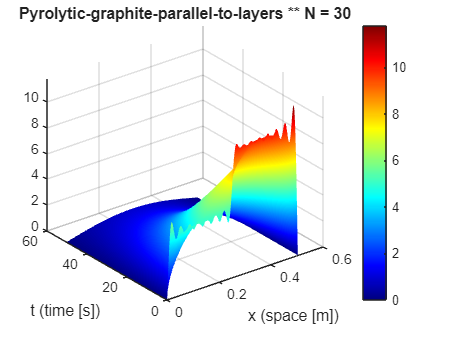

heatSolN  = buildHeatSol(material, L, phi, N, Tfinal, DHMS, 1);

**Live Script can be exported into a PDF, HTML, Word or LaTeX:**

% Uncomment the lines below to convert and/or open the PDF version of this live script 
% export("HeatEquationDemo.mlx")
% open HeatEquationDemo.pdf

*Thanks*

*THE END*

## *************   LOCAL FUNCTIONS   ********** ***

### buildHeatStruct

Go back to Structure section, Go back to Code Line 236

function u_n  = buildHeatStruct
syms t x n b_n L D u_n(x,t,n) lambda(n)
assume(n, "integer")
assume([L D], "positive")
lambda(n) = n*pi/L;
u_n(x,t,n) =  b_n .* sin(x*lambda(n)) .* exp(-t*D*lambda(n).^2) ;
end % end buildHeatStruct


### buildHeatSol

Go back

function [heatSolN, D, tau, b] = buildHeatSol(material, L, phi, N, Tfinal, DHMS, animationflag)
% The first 2 input arguments are mandatory to compute D and tau
% The first 4 input arguments are mandatory to compute heat solution
% 5th and 6th are mandatory to visualize: Tfinal+DHMS (Days,Hours,Minutes,Seconds)
% 7th input (is mandatory to see animation (any placeholder: 1,true, ...)

%%%%%%%%% Compute diffusivity of material %%%%%%%%%
if isstring(material) || ischar(material)
    load materials.mat DIFFUSIVITY   % load the dictionary (values in mm^2/s)
    D = DIFFUSIVITY(material) * 1e-6;  % convert from mm^2/s to m^2/s
elseif isnumeric(material)
    D = material;
    material = "Material with diffusivity D = " + D;
end
tau = L^2/D;

%%%%%%%%% CONVERSION OF TIME DURATION IN SECONDS %%%%%%%%%
%   5th input:  Tfinal (double, positive)
%   6th input:  DHMS   (string)  (= time unit, eg Days-Hours-Minutes-Seconds) 
%   Ex. if Tfinal = 30, DHMS = "minutes", then Tfinal_s = seconds(minutes(30)) = 1800 [s]
%   Ex. if Tfinal =  2, DHMS = "hours", then Tfinal_s = seconds(hours(2)) = 7200 [s]
if nargin >= 6
    Tfinal_s = seconds(eval(DHMS + "(" + Tfinal + ")")); % [s]
end

%%%%%%%%% TODO Build heat solution here %%%%%%%%%
if nargin >= 4
% 
syms x t n b(n)
assume(n, ["positive", "integer"])
% A:Compute Fourier coefficients (as symbolic function) using phi(x) and L
b(n) = simplify(2/L*int( phi(x)* sin(n*pi/L*x) , 0, L));

% B: Build heat structure
heatStruct = buildHeatStruct;

% C: Embedding b(n), L and D in the heat structure
heatStructEmb(x,t,n) = subs(heatStruct, sym(["b_n" "L" "D"]), [b L D]);

% D: Build solution by summing up N terms of the series
heatSolN = simplify(symsum(heatStructEmb, n, 1, N));
else 
    heatSolN = [];
end


%%%%%%%%%  FLEXIBLE VISUALIZATION %%%%%%%%%
if nargin == 6
    % Visualize just the final heat surface
    figure
    fsurf(heatSolN, [0 L 0 Tfinal_s], "EdgeColor","interp");
    colormap jet
    colorbar
    title(material)
    xlabel("x (space [m])")
    ylabel("t (time [s])")

elseif nargin == 7
    % Do ANIMATION
    bNum = double(subs(b, n, 1:N));
    xResolution = max(500, 2.5*N/2);
    tResolution = 100;
    xnum = linspace(0,L,xResolution);
    tnum = linspace(0, Tfinal_s, tResolution);
    [XX, TT] = meshgrid(xnum,tnum);
    
    colormap jet
    TEMP = zeros(size(XX));
    for k = 1:N
        lambda_k = k*pi/L;
        TEMP = TEMP +  bNum(k) * sin(lambda_k*XX) .* exp(-TT*D*(lambda_k)^2);
        surf(XX,TT,TEMP)
        title(material + " ** N = " +  k)
        xlabel("x (space [m])")
        ylabel("t (time [s])")
        shading interp
        colorbar
        drawnow
    end % loop k
    
end % if nargin

end % function buildHeatSol

*Go* back

*Copyright 2021-2024 The MathWorks, Inc.*